%Exercise 3

%PART 1
% Not feeling convinced by your single experiment (good scientist!),
%you repeat it under identical conditions. This time you measure 5 quanta 
% that were released. Your sample size has now doubled, to two measurements.
% You now want to take into account both measurements when you assess the 
% likelihoods of different possible values of the underlying release probability.
% To do so, assume that the two measurements in this sample are independent of
% one another; that is, the value of each result had no bearing on the other.
%In this case, the total likelihood is simply the product of the likelihoods 
% associated with each separate measurement. It is also typical to compute 
% the logarithm of each likelihood and take their sum, which is often more convenient. 
% What are the values of the total likelihood and total log-likelihood in this example, 
% if we assume that the true release probability is 0.1?

%PART 2
% Of course, knowing those values of the likelihood and log-likelihood 
% is not particularly useful until you can compare them to the values 
% computed for other possible values for the release probability, 
% so you can determine which value of release probability is most likely, 
% given the data. Therefore, compute the full likelihood and log-likelihood 
% functions using deciles of release probability between 0 and 1. What is 
% the maximum value? Can you improve your estimate by computing the functions 
% at a higher resolution? How does the estimate improve as you increase the sample size?

%PART 1
p = 0.1

p = 0.1000

n = 14

n = 14

num_experiments = 2

num_experiments = 2

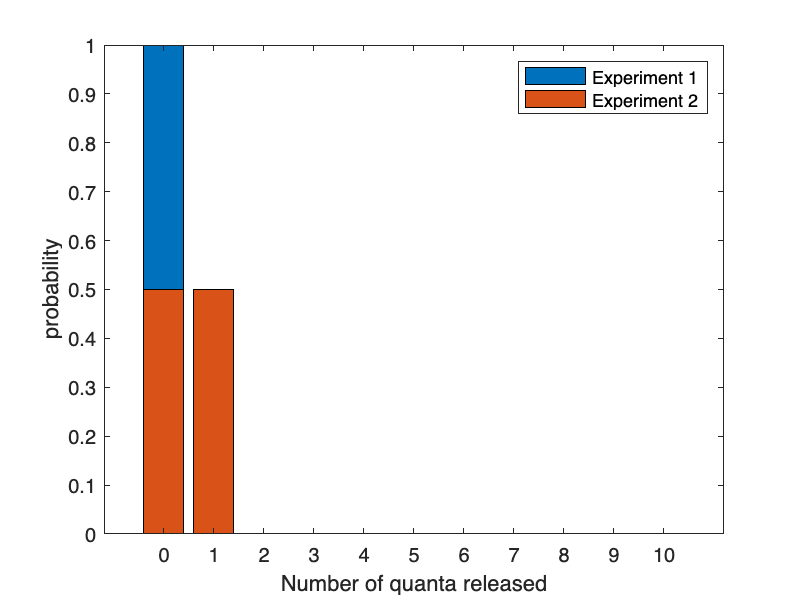

outcome1 = binornd(n,p,num_experiments,1);
outcome2 = binornd(n,p,num_experiments,1);


edges = -0.5:10.5;
counts1 = histcounts(outcome1,edges);
counts2 = histcounts(outcome2,edges);


xAxis = edges(1:end-1)+diff(edges)/2;
bar(xAxis, counts1./sum(counts1), "grouped")
hold on
bar(xAxis, counts2./sum(counts2), "grouped")
legend("Experiment 1", "Experiment 2")
ylabel("probability")
xlabel("Number of quanta released")


log_likelihood = log(counts1)+log(counts2)

log_likelihood =     0.6931      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf


sprintf("log likelihood when release probability is %.2f is:  %.2f.  ",p, log_likelihood)

ans = "log likelihood when release probability is 0.10 is:  0.69.  log likelihood when release probability is -Inf is:  -Inf.  log likelihood when release probability is -Inf is:  -Inf.  log likelihood when release probability is -Inf is:  -Inf.  log likelihood when release probability is -Inf is:  -Inf.  log likelihood when release probability is -Inf is:  -Inf.  "

%PART 2
%likelihood and log likelihood for range of probs and repeats of experiment
experiment_range = [1:24:100]

experiment_range =      1    25    49    73    97


probability_range = [0.1:0.1:1.0]

probability_range =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


for p = probability_range
    n = 14;
    for num_experiments = experiment_range
        outcomes = binornd(n,p, num_experiments, 1);
        counts1 = histcounts(outcome1);
        counts2 = histcounts(outcome2);
        log_likelihood = log(counts1)+log(counts2);
        sprintf("When release probability = %.2f and experiment is repeated %d times: %d quanta released. Log likelyhood= %.2f", p, num_experiments, outcomes, log_likelihood)
    end 
end

ans = "When release probability = 0.10 and experiment is repeated 1 times: 1 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.10 and experiment is repeated 25 times: 0 quanta released. Log likelyhood= 3.00When release probability = 0.00 and experiment is repeated 1 times: 0 quanta released. Log likelyhood= 0.00When release probability = 2.00 and experiment is repeated 1 times: 2 quanta released. Log likelyhood= 3.00When release probability = 0.00 and experiment is repeated 2 times: 1 quanta released. Log likelyhood= 2.00When release probability = 1.00 and experiment is repeated 5 times: 2 quanta released. Log likelyhood= 0.00When release probability = 2.00 and experiment is repeated 2 times: 2 quanta released. Log likelyhood= 1.00When release probability = 0.00 and experiment is repeated 1 times: 1 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.10 and experiment is repeated 49 times: 3 quanta released. Log likelyhood= 3.00When release probability = 1.00 and experiment is repeated 1 times: 1 quanta released. Log likelyhood= 1.00When release probability = 2.00 and experiment is repeated 0 times: 0 quanta released. Log likelyhood= 1.00When release probability = 0.00 and experiment is repeated 2 times: 0 quanta released. Log likelyhood= 1.00When release probability = 0.00 and experiment is repeated 0 times: 1 quanta released. Log likelyhood= 4.00When release probability = 1.00 and experiment is repeated 3 times: 1 quanta released. Log likelyhood= 0.00When release probability = 0.00 and experiment is repeated 2 times: 0 quanta released. Log likelyhood= 1.00When release probability = 0.00 and experiment is repeated 1 times: 2 quanta released. Log likelyhood= 1.00When release probability = 2.00 and experiment is repeated 1 times: 2 quanta released. Log likelyhood= 1.00When release probability = 0.

ans = "When release probability = 0.10 and experiment is repeated 73 times: 2 quanta released. Log likelyhood= 2.00When release probability = 1.00 and experiment is repeated 2 times: 2 quanta released. Log likelyhood= 2.00When release probability = 0.00 and experiment is repeated 0 times: 0 quanta released. Log likelyhood= 1.00When release probability = 2.00 and experiment is repeated 0 times: 0 quanta released. Log likelyhood= 4.00When release probability = 0.00 and experiment is repeated 1 times: 2 quanta released. Log likelyhood= 2.00When release probability = 0.00 and experiment is repeated 1 times: 3 quanta released. Log likelyhood= 0.00When release probability = 1.00 and experiment is repeated 0 times: 0 quanta released. Log likelyhood= 3.00When release probability = 0.00 and experiment is repeated 1 times: 1 quanta released. Log likelyhood= 1.00When release probability = 1.00 and experiment is repeated 0 times: 2 quanta released. Log likelyhood= 2.00When release probability = 3.

ans = "When release probability = 0.10 and experiment is repeated 97 times: 1 quanta released. Log likelyhood= 0.00When release probability = 1.00 and experiment is repeated 2 times: 2 quanta released. Log likelyhood= 2.00When release probability = 1.00 and experiment is repeated 0 times: 1 quanta released. Log likelyhood= 1.00When release probability = 0.00 and experiment is repeated 2 times: 0 quanta released. Log likelyhood= 1.00When release probability = 1.00 and experiment is repeated 1 times: 2 quanta released. Log likelyhood= 1.00When release probability = 1.00 and experiment is repeated 1 times: 4 quanta released. Log likelyhood= 2.00When release probability = 0.00 and experiment is repeated 1 times: 1 quanta released. Log likelyhood= 1.00When release probability = 0.00 and experiment is repeated 1 times: 0 quanta released. Log likelyhood= 2.00When release probability = 1.00 and experiment is repeated 3 times: 2 quanta released. Log likelyhood= 2.00When release probability = 1.

ans = "When release probability = 0.20 and experiment is repeated 1 times: 4 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.20 and experiment is repeated 25 times: 3 quanta released. Log likelyhood= 1.00When release probability = 4.00 and experiment is repeated 0 times: 3 quanta released. Log likelyhood= 3.00When release probability = 3.00 and experiment is repeated 3 times: 5 quanta released. Log likelyhood= 3.00When release probability = 1.00 and experiment is repeated 4 times: 4 quanta released. Log likelyhood= 3.00When release probability = 3.00 and experiment is repeated 3 times: 5 quanta released. Log likelyhood= 5.00When release probability = 2.00 and experiment is repeated 4 times: 2 quanta released. Log likelyhood= 3.00When release probability = 0.00 and experiment is repeated 2 times: 3 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.20 and experiment is repeated 49 times: 3 quanta released. Log likelyhood= 3.00When release probability = 2.00 and experiment is repeated 2 times: 3 quanta released. Log likelyhood= 0.00When release probability = 2.00 and experiment is repeated 2 times: 0 quanta released. Log likelyhood= 1.00When release probability = 3.00 and experiment is repeated 3 times: 3 quanta released. Log likelyhood= 6.00When release probability = 0.00 and experiment is repeated 2 times: 2 quanta released. Log likelyhood= 3.00When release probability = 4.00 and experiment is repeated 3 times: 4 quanta released. Log likelyhood= 3.00When release probability = 4.00 and experiment is repeated 2 times: 4 quanta released. Log likelyhood= 3.00When release probability = 3.00 and experiment is repeated 2 times: 1 quanta released. Log likelyhood= 1.00When release probability = 4.00 and experiment is repeated 8 times: 1 quanta released. Log likelyhood= 3.00When release probability = 2.

ans = "When release probability = 0.20 and experiment is repeated 73 times: 2 quanta released. Log likelyhood= 6.00When release probability = 1.00 and experiment is repeated 1 times: 2 quanta released. Log likelyhood= 4.00When release probability = 1.00 and experiment is repeated 1 times: 3 quanta released. Log likelyhood= 5.00When release probability = 3.00 and experiment is repeated 0 times: 2 quanta released. Log likelyhood= 2.00When release probability = 2.00 and experiment is repeated 2 times: 3 quanta released. Log likelyhood= 2.00When release probability = 1.00 and experiment is repeated 4 times: 3 quanta released. Log likelyhood= 3.00When release probability = 4.00 and experiment is repeated 2 times: 5 quanta released. Log likelyhood= 1.00When release probability = 1.00 and experiment is repeated 4 times: 2 quanta released. Log likelyhood= 4.00When release probability = 3.00 and experiment is repeated 1 times: 3 quanta released. Log likelyhood= 2.00When release probability = 4.

ans = "When release probability = 0.20 and experiment is repeated 97 times: 1 quanta released. Log likelyhood= 2.00When release probability = 3.00 and experiment is repeated 4 times: 5 quanta released. Log likelyhood= 1.00When release probability = 2.00 and experiment is repeated 3 times: 2 quanta released. Log likelyhood= 4.00When release probability = 6.00 and experiment is repeated 1 times: 2 quanta released. Log likelyhood= 2.00When release probability = 6.00 and experiment is repeated 2 times: 3 quanta released. Log likelyhood= 1.00When release probability = 3.00 and experiment is repeated 3 times: 0 quanta released. Log likelyhood= 4.00When release probability = 3.00 and experiment is repeated 3 times: 0 quanta released. Log likelyhood= 1.00When release probability = 1.00 and experiment is repeated 4 times: 4 quanta released. Log likelyhood= 0.00When release probability = 3.00 and experiment is repeated 5 times: 2 quanta released. Log likelyhood= 5.00When release probability = 6.

ans = "When release probability = 0.30 and experiment is repeated 1 times: 4 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.30 and experiment is repeated 25 times: 7 quanta released. Log likelyhood= 5.00When release probability = 5.00 and experiment is repeated 3 times: 3 quanta released. Log likelyhood= 7.00When release probability = 5.00 and experiment is repeated 5 times: 10 quanta released. Log likelyhood= 3.00When release probability = 3.00 and experiment is repeated 3 times: 4 quanta released. Log likelyhood= 4.00When release probability = 4.00 and experiment is repeated 9 times: 3 quanta released. Log likelyhood= 2.00When release probability = 2.00 and experiment is repeated 3 times: 4 quanta released. Log likelyhood= 3.00When release probability = 5.00 and experiment is repeated 7 times: 7 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.30 and experiment is repeated 49 times: 6 quanta released. Log likelyhood= 2.00When release probability = 9.00 and experiment is repeated 9 times: 6 quanta released. Log likelyhood= 6.00When release probability = 6.00 and experiment is repeated 5 times: 3 quanta released. Log likelyhood= 0.00When release probability = 2.00 and experiment is repeated 2 times: 4 quanta released. Log likelyhood= 2.00When release probability = 6.00 and experiment is repeated 2 times: 2 quanta released. Log likelyhood= 2.00When release probability = 4.00 and experiment is repeated 4 times: 3 quanta released. Log likelyhood= 4.00When release probability = 3.00 and experiment is repeated 5 times: 5 quanta released. Log likelyhood= 2.00When release probability = 2.00 and experiment is repeated 0 times: 6 quanta released. Log likelyhood= 2.00When release probability = 7.00 and experiment is repeated 4 times: 2 quanta released. Log likelyhood= 6.00When release probability = 2.

ans = "When release probability = 0.30 and experiment is repeated 73 times: 4 quanta released. Log likelyhood= 5.00When release probability = 4.00 and experiment is repeated 3 times: 5 quanta released. Log likelyhood= 1.00When release probability = 3.00 and experiment is repeated 3 times: 6 quanta released. Log likelyhood= 3.00When release probability = 4.00 and experiment is repeated 5 times: 3 quanta released. Log likelyhood= 1.00When release probability = 6.00 and experiment is repeated 5 times: 7 quanta released. Log likelyhood= 4.00When release probability = 7.00 and experiment is repeated 2 times: 8 quanta released. Log likelyhood= 5.00When release probability = 4.00 and experiment is repeated 1 times: 9 quanta released. Log likelyhood= 3.00When release probability = 6.00 and experiment is repeated 3 times: 5 quanta released. Log likelyhood= 7.00When release probability = 2.00 and experiment is repeated 2 times: 2 quanta released. Log likelyhood= 7.00When release probability = 7.

ans = "When release probability = 0.30 and experiment is repeated 97 times: 5 quanta released. Log likelyhood= 5.00When release probability = 4.00 and experiment is repeated 5 times: 4 quanta released. Log likelyhood= 3.00When release probability = 5.00 and experiment is repeated 4 times: 5 quanta released. Log likelyhood= 7.00When release probability = 2.00 and experiment is repeated 3 times: 4 quanta released. Log likelyhood= 5.00When release probability = 3.00 and experiment is repeated 6 times: 3 quanta released. Log likelyhood= 4.00When release probability = 4.00 and experiment is repeated 3 times: 2 quanta released. Log likelyhood= 7.00When release probability = 3.00 and experiment is repeated 4 times: 6 quanta released. Log likelyhood= 6.00When release probability = 6.00 and experiment is repeated 4 times: 6 quanta released. Log likelyhood= 3.00When release probability = 1.00 and experiment is repeated 5 times: 4 quanta released. Log likelyhood= 3.00When release probability = 4.

ans = "When release probability = 0.40 and experiment is repeated 1 times: 3 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.40 and experiment is repeated 25 times: 8 quanta released. Log likelyhood= 4.00When release probability = 7.00 and experiment is repeated 6 times: 5 quanta released. Log likelyhood= 6.00When release probability = 6.00 and experiment is repeated 6 times: 6 quanta released. Log likelyhood= 7.00When release probability = 6.00 and experiment is repeated 4 times: 4 quanta released. Log likelyhood= 3.00When release probability = 2.00 and experiment is repeated 5 times: 5 quanta released. Log likelyhood= 5.00When release probability = 7.00 and experiment is repeated 6 times: 7 quanta released. Log likelyhood= 4.00When release probability = 8.00 and experiment is repeated 0 times: 3 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.40 and experiment is repeated 49 times: 4 quanta released. Log likelyhood= 5.00When release probability = 5.00 and experiment is repeated 7 times: 8 quanta released. Log likelyhood= 7.00When release probability = 7.00 and experiment is repeated 4 times: 7 quanta released. Log likelyhood= 5.00When release probability = 6.00 and experiment is repeated 4 times: 5 quanta released. Log likelyhood= 4.00When release probability = 9.00 and experiment is repeated 7 times: 8 quanta released. Log likelyhood= 5.00When release probability = 5.00 and experiment is repeated 3 times: 5 quanta released. Log likelyhood= 7.00When release probability = 7.00 and experiment is repeated 5 times: 6 quanta released. Log likelyhood= 5.00When release probability = 6.00 and experiment is repeated 7 times: 4 quanta released. Log likelyhood= 5.00When release probability = 4.00 and experiment is repeated 5 times: 8 quanta released. Log likelyhood= 7.00When release probability = 8.

ans = "When release probability = 0.40 and experiment is repeated 73 times: 7 quanta released. Log likelyhood= 3.00When release probability = 5.00 and experiment is repeated 4 times: 8 quanta released. Log likelyhood= 6.00When release probability = 4.00 and experiment is repeated 6 times: 7 quanta released. Log likelyhood= 3.00When release probability = 5.00 and experiment is repeated 4 times: 7 quanta released. Log likelyhood= 2.00When release probability = 6.00 and experiment is repeated 6 times: 7 quanta released. Log likelyhood= 4.00When release probability = 6.00 and experiment is repeated 6 times: 9 quanta released. Log likelyhood= 3.00When release probability = 2.00 and experiment is repeated 4 times: 6 quanta released. Log likelyhood= 7.00When release probability = 5.00 and experiment is repeated 6 times: 6 quanta released. Log likelyhood= 4.00When release probability = 8.00 and experiment is repeated 7 times: 6 quanta released. Log likelyhood= 11.00When release probability = 8

ans = "When release probability = 0.40 and experiment is repeated 97 times: 3 quanta released. Log likelyhood= 5.00When release probability = 5.00 and experiment is repeated 3 times: 6 quanta released. Log likelyhood= 10.00When release probability = 8.00 and experiment is repeated 5 times: 5 quanta released. Log likelyhood= 9.00When release probability = 8.00 and experiment is repeated 4 times: 5 quanta released. Log likelyhood= 6.00When release probability = 7.00 and experiment is repeated 3 times: 10 quanta released. Log likelyhood= 5.00When release probability = 5.00 and experiment is repeated 3 times: 7 quanta released. Log likelyhood= 4.00When release probability = 7.00 and experiment is repeated 8 times: 5 quanta released. Log likelyhood= 7.00When release probability = 6.00 and experiment is repeated 5 times: 5 quanta released. Log likelyhood= 6.00When release probability = 6.00 and experiment is repeated 9 times: 8 quanta released. Log likelyhood= 6.00When release probability = 

ans = "When release probability = 0.50 and experiment is repeated 1 times: 4 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.50 and experiment is repeated 25 times: 4 quanta released. Log likelyhood= 7.00When release probability = 6.00 and experiment is repeated 5 times: 8 quanta released. Log likelyhood= 4.00When release probability = 7.00 and experiment is repeated 9 times: 5 quanta released. Log likelyhood= 7.00When release probability = 7.00 and experiment is repeated 10 times: 6 quanta released. Log likelyhood= 7.00When release probability = 7.00 and experiment is repeated 9 times: 9 quanta released. Log likelyhood= 9.00When release probability = 9.00 and experiment is repeated 7 times: 6 quanta released. Log likelyhood= 10.00When release probability = 6.00 and experiment is repeated 10 times: 7 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.50 and experiment is repeated 49 times: 12 quanta released. Log likelyhood= 5.00When release probability = 6.00 and experiment is repeated 7 times: 12 quanta released. Log likelyhood= 7.00When release probability = 8.00 and experiment is repeated 7 times: 3 quanta released. Log likelyhood= 6.00When release probability = 6.00 and experiment is repeated 4 times: 5 quanta released. Log likelyhood= 9.00When release probability = 7.00 and experiment is repeated 9 times: 8 quanta released. Log likelyhood= 7.00When release probability = 8.00 and experiment is repeated 9 times: 6 quanta released. Log likelyhood= 10.00When release probability = 6.00 and experiment is repeated 4 times: 4 quanta released. Log likelyhood= 8.00When release probability = 5.00 and experiment is repeated 8 times: 8 quanta released. Log likelyhood= 8.00When release probability = 7.00 and experiment is repeated 8 times: 3 quanta released. Log likelyhood= 2.00When release probability =

ans = "When release probability = 0.50 and experiment is repeated 73 times: 9 quanta released. Log likelyhood= 3.00When release probability = 8.00 and experiment is repeated 3 times: 7 quanta released. Log likelyhood= 6.00When release probability = 8.00 and experiment is repeated 7 times: 7 quanta released. Log likelyhood= 8.00When release probability = 7.00 and experiment is repeated 6 times: 10 quanta released. Log likelyhood= 6.00When release probability = 8.00 and experiment is repeated 7 times: 4 quanta released. Log likelyhood= 9.00When release probability = 3.00 and experiment is repeated 9 times: 8 quanta released. Log likelyhood= 8.00When release probability = 4.00 and experiment is repeated 4 times: 12 quanta released. Log likelyhood= 8.00When release probability = 9.00 and experiment is repeated 7 times: 5 quanta released. Log likelyhood= 8.00When release probability = 7.00 and experiment is repeated 9 times: 6 quanta released. Log likelyhood= 7.00When release probability = 

ans = "When release probability = 0.50 and experiment is repeated 97 times: 9 quanta released. Log likelyhood= 8.00When release probability = 6.00 and experiment is repeated 5 times: 7 quanta released. Log likelyhood= 7.00When release probability = 9.00 and experiment is repeated 6 times: 5 quanta released. Log likelyhood= 9.00When release probability = 9.00 and experiment is repeated 6 times: 5 quanta released. Log likelyhood= 8.00When release probability = 10.00 and experiment is repeated 5 times: 10 quanta released. Log likelyhood= 6.00When release probability = 6.00 and experiment is repeated 6 times: 9 quanta released. Log likelyhood= 8.00When release probability = 7.00 and experiment is repeated 8 times: 5 quanta released. Log likelyhood= 4.00When release probability = 7.00 and experiment is repeated 7 times: 8 quanta released. Log likelyhood= 6.00When release probability = 10.00 and experiment is repeated 6 times: 4 quanta released. Log likelyhood= 7.00When release probability =

ans = "When release probability = 0.60 and experiment is repeated 1 times: 7 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.60 and experiment is repeated 25 times: 8 quanta released. Log likelyhood= 8.00When release probability = 10.00 and experiment is repeated 8 times: 10 quanta released. Log likelyhood= 10.00When release probability = 10.00 and experiment is repeated 8 times: 12 quanta released. Log likelyhood= 6.00When release probability = 10.00 and experiment is repeated 7 times: 11 quanta released. Log likelyhood= 8.00When release probability = 4.00 and experiment is repeated 10 times: 9 quanta released. Log likelyhood= 5.00When release probability = 9.00 and experiment is repeated 7 times: 11 quanta released. Log likelyhood= 9.00When release probability = 10.00 and experiment is repeated 7 times: 10 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.60 and experiment is repeated 49 times: 8 quanta released. Log likelyhood= 11.00When release probability = 5.00 and experiment is repeated 10 times: 8 quanta released. Log likelyhood= 11.00When release probability = 7.00 and experiment is repeated 9 times: 9 quanta released. Log likelyhood= 8.00When release probability = 9.00 and experiment is repeated 8 times: 11 quanta released. Log likelyhood= 8.00When release probability = 9.00 and experiment is repeated 8 times: 10 quanta released. Log likelyhood= 9.00When release probability = 10.00 and experiment is repeated 8 times: 7 quanta released. Log likelyhood= 8.00When release probability = 11.00 and experiment is repeated 10 times: 8 quanta released. Log likelyhood= 8.00When release probability = 7.00 and experiment is repeated 7 times: 10 quanta released. Log likelyhood= 6.00When release probability = 9.00 and experiment is repeated 9 times: 10 quanta released. Log likelyhood= 5.00When release probab

ans = "When release probability = 0.60 and experiment is repeated 73 times: 8 quanta released. Log likelyhood= 7.00When release probability = 8.00 and experiment is repeated 9 times: 6 quanta released. Log likelyhood= 8.00When release probability = 11.00 and experiment is repeated 8 times: 9 quanta released. Log likelyhood= 9.00When release probability = 9.00 and experiment is repeated 10 times: 10 quanta released. Log likelyhood= 8.00When release probability = 7.00 and experiment is repeated 8 times: 5 quanta released. Log likelyhood= 9.00When release probability = 8.00 and experiment is repeated 8 times: 4 quanta released. Log likelyhood= 5.00When release probability = 9.00 and experiment is repeated 7 times: 6 quanta released. Log likelyhood= 7.00When release probability = 9.00 and experiment is repeated 9 times: 5 quanta released. Log likelyhood= 7.00When release probability = 10.00 and experiment is repeated 7 times: 7 quanta released. Log likelyhood= 11.00When release probability

ans = "When release probability = 0.60 and experiment is repeated 97 times: 8 quanta released. Log likelyhood= 9.00When release probability = 5.00 and experiment is repeated 6 times: 6 quanta released. Log likelyhood= 11.00When release probability = 8.00 and experiment is repeated 10 times: 8 quanta released. Log likelyhood= 9.00When release probability = 10.00 and experiment is repeated 9 times: 6 quanta released. Log likelyhood= 8.00When release probability = 10.00 and experiment is repeated 10 times: 7 quanta released. Log likelyhood= 8.00When release probability = 12.00 and experiment is repeated 12 times: 8 quanta released. Log likelyhood= 9.00When release probability = 10.00 and experiment is repeated 8 times: 11 quanta released. Log likelyhood= 9.00When release probability = 10.00 and experiment is repeated 6 times: 7 quanta released. Log likelyhood= 7.00When release probability = 9.00 and experiment is repeated 5 times: 10 quanta released. Log likelyhood= 8.00When release proba

ans = "When release probability = 0.70 and experiment is repeated 1 times: 13 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.70 and experiment is repeated 25 times: 10 quanta released. Log likelyhood= 10.00When release probability = 8.00 and experiment is repeated 6 times: 12 quanta released. Log likelyhood= 10.00When release probability = 9.00 and experiment is repeated 7 times: 12 quanta released. Log likelyhood= 11.00When release probability = 12.00 and experiment is repeated 11 times: 11 quanta released. Log likelyhood= 9.00When release probability = 11.00 and experiment is repeated 12 times: 11 quanta released. Log likelyhood= 11.00When release probability = 9.00 and experiment is repeated 10 times: 11 quanta released. Log likelyhood= 8.00When release probability = 8.00 and experiment is repeated 6 times: 10 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.70 and experiment is repeated 49 times: 10 quanta released. Log likelyhood= 7.00When release probability = 10.00 and experiment is repeated 10 times: 12 quanta released. Log likelyhood= 11.00When release probability = 9.00 and experiment is repeated 13 times: 11 quanta released. Log likelyhood= 12.00When release probability = 10.00 and experiment is repeated 7 times: 8 quanta released. Log likelyhood= 9.00When release probability = 10.00 and experiment is repeated 11 times: 11 quanta released. Log likelyhood= 11.00When release probability = 9.00 and experiment is repeated 7 times: 12 quanta released. Log likelyhood= 12.00When release probability = 7.00 and experiment is repeated 9 times: 10 quanta released. Log likelyhood= 9.00When release probability = 8.00 and experiment is repeated 9 times: 9 quanta released. Log likelyhood= 12.00When release probability = 11.00 and experiment is repeated 11 times: 9 quanta released. Log likelyhood= 10.00When rele

ans = "When release probability = 0.70 and experiment is repeated 73 times: 10 quanta released. Log likelyhood= 9.00When release probability = 7.00 and experiment is repeated 9 times: 12 quanta released. Log likelyhood= 10.00When release probability = 11.00 and experiment is repeated 11 times: 10 quanta released. Log likelyhood= 8.00When release probability = 7.00 and experiment is repeated 14 times: 10 quanta released. Log likelyhood= 12.00When release probability = 9.00 and experiment is repeated 11 times: 10 quanta released. Log likelyhood= 8.00When release probability = 11.00 and experiment is repeated 8 times: 7 quanta released. Log likelyhood= 12.00When release probability = 4.00 and experiment is repeated 14 times: 11 quanta released. Log likelyhood= 10.00When release probability = 10.00 and experiment is repeated 10 times: 11 quanta released. Log likelyhood= 7.00When release probability = 8.00 and experiment is repeated 10 times: 11 quanta released. Log likelyhood= 8.00When rel

ans = "When release probability = 0.70 and experiment is repeated 97 times: 8 quanta released. Log likelyhood= 10.00When release probability = 12.00 and experiment is repeated 10 times: 12 quanta released. Log likelyhood= 9.00When release probability = 9.00 and experiment is repeated 11 times: 8 quanta released. Log likelyhood= 9.00When release probability = 11.00 and experiment is repeated 11 times: 7 quanta released. Log likelyhood= 7.00When release probability = 9.00 and experiment is repeated 10 times: 9 quanta released. Log likelyhood= 10.00When release probability = 10.00 and experiment is repeated 12 times: 11 quanta released. Log likelyhood= 11.00When release probability = 12.00 and experiment is repeated 7 times: 7 quanta released. Log likelyhood= 11.00When release probability = 13.00 and experiment is repeated 12 times: 8 quanta released. Log likelyhood= 9.00When release probability = 5.00 and experiment is repeated 7 times: 9 quanta released. Log likelyhood= 9.00When release

ans = "When release probability = 0.80 and experiment is repeated 1 times: 11 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.80 and experiment is repeated 25 times: 11 quanta released. Log likelyhood= 14.00When release probability = 11.00 and experiment is repeated 12 times: 12 quanta released. Log likelyhood= 12.00When release probability = 11.00 and experiment is repeated 10 times: 12 quanta released. Log likelyhood= 12.00When release probability = 14.00 and experiment is repeated 10 times: 12 quanta released. Log likelyhood= 8.00When release probability = 11.00 and experiment is repeated 13 times: 7 quanta released. Log likelyhood= 11.00When release probability = 13.00 and experiment is repeated 9 times: 11 quanta released. Log likelyhood= 13.00When release probability = 11.00 and experiment is repeated 12 times: 9 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.80 and experiment is repeated 49 times: 10 quanta released. Log likelyhood= 11.00When release probability = 10.00 and experiment is repeated 7 times: 9 quanta released. Log likelyhood= 10.00When release probability = 12.00 and experiment is repeated 11 times: 11 quanta released. Log likelyhood= 12.00When release probability = 10.00 and experiment is repeated 11 times: 14 quanta released. Log likelyhood= 12.00When release probability = 11.00 and experiment is repeated 12 times: 11 quanta released. Log likelyhood= 13.00When release probability = 10.00 and experiment is repeated 11 times: 11 quanta released. Log likelyhood= 14.00When release probability = 10.00 and experiment is repeated 9 times: 12 quanta released. Log likelyhood= 11.00When release probability = 11.00 and experiment is repeated 9 times: 11 quanta released. Log likelyhood= 11.00When release probability = 10.00 and experiment is repeated 10 times: 10 quanta released. Log likelyhood= 10.0

ans = "When release probability = 0.80 and experiment is repeated 73 times: 9 quanta released. Log likelyhood= 12.00When release probability = 10.00 and experiment is repeated 14 times: 10 quanta released. Log likelyhood= 11.00When release probability = 14.00 and experiment is repeated 9 times: 11 quanta released. Log likelyhood= 8.00When release probability = 11.00 and experiment is repeated 11 times: 12 quanta released. Log likelyhood= 11.00When release probability = 12.00 and experiment is repeated 13 times: 12 quanta released. Log likelyhood= 12.00When release probability = 10.00 and experiment is repeated 11 times: 13 quanta released. Log likelyhood= 13.00When release probability = 10.00 and experiment is repeated 11 times: 10 quanta released. Log likelyhood= 11.00When release probability = 11.00 and experiment is repeated 11 times: 14 quanta released. Log likelyhood= 13.00When release probability = 9.00 and experiment is repeated 10 times: 10 quanta released. Log likelyhood= 11.0

ans = "When release probability = 0.80 and experiment is repeated 97 times: 11 quanta released. Log likelyhood= 13.00When release probability = 10.00 and experiment is repeated 10 times: 10 quanta released. Log likelyhood= 12.00When release probability = 11.00 and experiment is repeated 11 times: 11 quanta released. Log likelyhood= 12.00When release probability = 12.00 and experiment is repeated 13 times: 14 quanta released. Log likelyhood= 10.00When release probability = 9.00 and experiment is repeated 12 times: 8 quanta released. Log likelyhood= 12.00When release probability = 10.00 and experiment is repeated 10 times: 11 quanta released. Log likelyhood= 9.00When release probability = 13.00 and experiment is repeated 11 times: 10 quanta released. Log likelyhood= 10.00When release probability = 12.00 and experiment is repeated 12 times: 14 quanta released. Log likelyhood= 14.00When release probability = 10.00 and experiment is repeated 11 times: 8 quanta released. Log likelyhood= 11.0

ans = "When release probability = 0.90 and experiment is repeated 1 times: 13 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.90 and experiment is repeated 25 times: 13 quanta released. Log likelyhood= 13.00When release probability = 14.00 and experiment is repeated 13 times: 12 quanta released. Log likelyhood= 13.00When release probability = 13.00 and experiment is repeated 14 times: 12 quanta released. Log likelyhood= 13.00When release probability = 12.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 10.00When release probability = 14.00 and experiment is repeated 14 times: 13 quanta released. Log likelyhood= 12.00When release probability = 14.00 and experiment is repeated 13 times: 11 quanta released. Log likelyhood= 14.00When release probability = 13.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 0.90 and experiment is repeated 49 times: 14 quanta released. Log likelyhood= 14.00When release probability = 13.00 and experiment is repeated 13 times: 12 quanta released. Log likelyhood= 14.00When release probability = 12.00 and experiment is repeated 14 times: 13 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 11 times: 12 quanta released. Log likelyhood= 13.00When release probability = 11.00 and experiment is repeated 12 times: 14 quanta released. Log likelyhood= 13.00When release probability = 12.00 and experiment is repeated 12 times: 13 quanta released. Log likelyhood= 13.00When release probability = 13.00 and experiment is repeated 13 times: 14 quanta released. Log likelyhood= 14.00When release probability = 13.00 and experiment is repeated 14 times: 13 quanta released. Log likelyhood= 14.00When release probability = 13.00 and experiment is repeated 11 times: 12 quanta released. Log likelyhood= 

ans = "When release probability = 0.90 and experiment is repeated 73 times: 14 quanta released. Log likelyhood= 11.00When release probability = 13.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 13.00When release probability = 12.00 and experiment is repeated 13 times: 14 quanta released. Log likelyhood= 13.00When release probability = 12.00 and experiment is repeated 13 times: 13 quanta released. Log likelyhood= 13.00When release probability = 13.00 and experiment is repeated 13 times: 14 quanta released. Log likelyhood= 12.00When release probability = 14.00 and experiment is repeated 12 times: 13 quanta released. Log likelyhood= 13.00When release probability = 13.00 and experiment is repeated 14 times: 11 quanta released. Log likelyhood= 12.00When release probability = 12.00 and experiment is repeated 12 times: 13 quanta released. Log likelyhood= 13.00When release probability = 14.00 and experiment is repeated 9 times: 13 quanta released. Log likelyhood= 1

ans = "When release probability = 0.90 and experiment is repeated 97 times: 13 quanta released. Log likelyhood= 13.00When release probability = 13.00 and experiment is repeated 14 times: 13 quanta released. Log likelyhood= 14.00When release probability = 10.00 and experiment is repeated 12 times: 13 quanta released. Log likelyhood= 14.00When release probability = 13.00 and experiment is repeated 13 times: 13 quanta released. Log likelyhood= 13.00When release probability = 13.00 and experiment is repeated 12 times: 12 quanta released. Log likelyhood= 12.00When release probability = 12.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 13.00When release probability = 13.00 and experiment is repeated 14 times: 13 quanta released. Log likelyhood= 13.00When release probability = 11.00 and experiment is repeated 11 times: 12 quanta released. Log likelyhood= 13.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 

ans = "When release probability = 1.00 and experiment is repeated 1 times: 14 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 1.00 and experiment is repeated 25 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 0.69When release probability = 0.69 and experiment is repeated "

ans = "When release probability = 1.00 and experiment is repeated 49 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 

ans = "When release probability = 1.00 and experiment is repeated 73 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 

ans = "When release probability = 1.00 and experiment is repeated 97 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 14.00When release probability = 14.00 and experiment is repeated 14 times: 14 quanta released. Log likelyhood= 